# Extract all the topics of interest from ROSBAG

% requirements - 

ROS toolbox

Mapping toolbox

rosbagReader.m script in same location as this file

clc
clear
% Each bag can be passed directly and named after the experiment
% the output of custom rosbagReader function is to generate dataset of all
% topics and combine all the readings in entire rosbag under one header

%flat_concrete = rosbagReader('D:\husky_sysID\dataset_diffTerrain\concrete_2023-06-16-13-48-28.bag');
clothoid_1 = rosbagReader('D:\husky_sysID\dataset_Clothoid\fsc_v_0.7_m_0006_2023-05-06-15-20-49.bag');


%bank_grass = rosbagReader('fsc_v_0.2_m_0002_2023-05-06-14-12-47.bag');


**INPUT : Command Velocity**

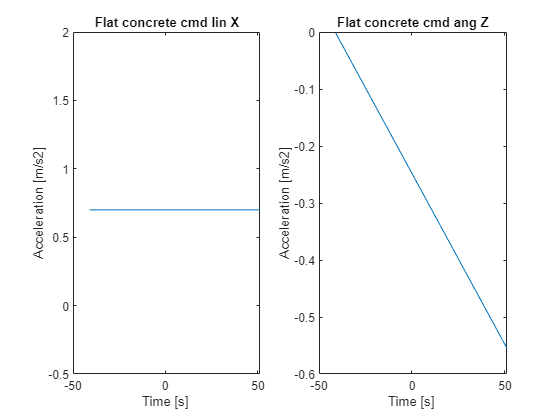

cmd.linX = clothoid_1.husky_velocity_controller_cmd_vel.Linear.X;
cmd.angZ = clothoid_1.husky_velocity_controller_cmd_vel.Angular.Z;
Reltime = clothoid_1.husky_velocity_controller_cmd_vel.RelTime;

fcmd = figure();
subplot(1,2,1)
plot(Reltime,cmd.linX)
title('Flat concrete cmd lin X')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(1,2,2)
plot(Reltime,cmd.angZ)
title('Flat concrete cmd ang Z')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

**Realized IMU Data**

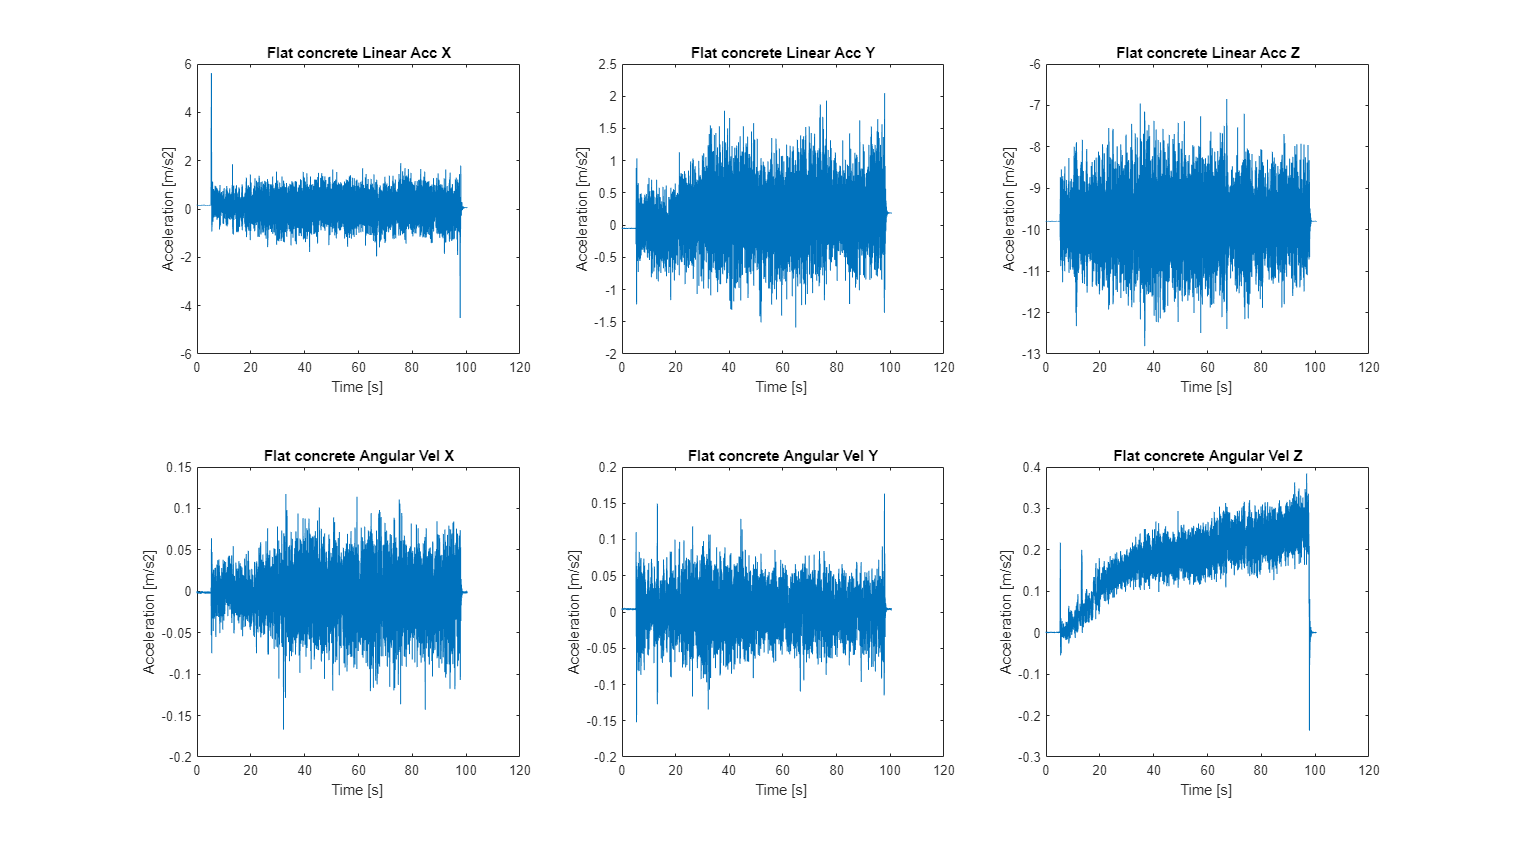

%flat_concrete.joint_states.Velocity
% Plotting each topic / any quantity becomes easier
acc.X = clothoid_1.gx5_imu_data.LinearAcceleration.X;
acc.Y = clothoid_1.gx5_imu_data.LinearAcceleration.Y;
acc.Z = clothoid_1.gx5_imu_data.LinearAcceleration.Z;
ang.X = clothoid_1.gx5_imu_data.AngularVelocity.X;
ang.Y = clothoid_1.gx5_imu_data.AngularVelocity.Y;
ang.Z = clothoid_1.gx5_imu_data.AngularVelocity.Z;
% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = clothoid_1.gx5_imu_data.RelTime;


f0 = figure();
subplot(2,3,1)
plot(Reltime,acc.X)
title('Flat concrete Linear Acc X')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(2,3,2)
plot(Reltime,acc.Y)
title('Flat concrete Linear Acc Y')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(2,3,3)
plot(Reltime,acc.Z)
title('Flat concrete Linear Acc Z')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(2,3,4)
plot(Reltime,ang.X)
title('Flat concrete Angular Vel X')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(2,3,5)
plot(Reltime,ang.Y)
title('Flat concrete Angular Vel Y')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

subplot(2,3,6)
plot(Reltime,ang.Z)
title('Flat concrete Angular Vel Z')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

set(f0,'Units','normalized','Position',[0 0 1.5 1.5])

## **Convert the GPS data to ENU-Carthesian coordinate frame**

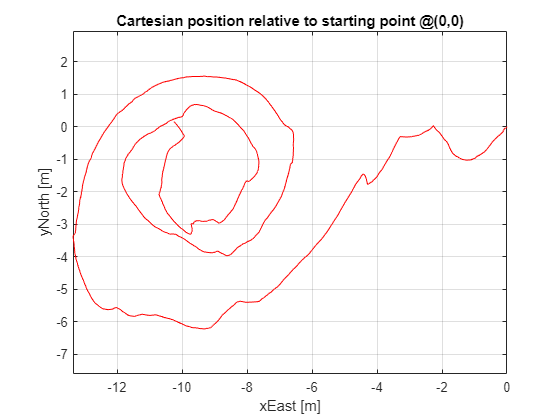

%Lets now plot navsatfix and coverted the quantities using geodetic to enu
%func and have a trajectory of robot

gpsLat = clothoid_1.piksi_multi_position_navsatfix_best_fix.Latitude;
gpsLon = clothoid_1.piksi_multi_position_navsatfix_best_fix.Longitude;
gpsAlt = clothoid_1.piksi_multi_position_navsatfix_best_fix.Altitude;
gpsReltime = clothoid_1.piksi_multi_position_navsatfix_best_fix.RelTime;
% Define the reference coordinates, corresponding to (0,0,0) coordinates
% let's pick the starting point of the trajectory according to the /bestfix
% topic
[xEastGPS, yNorthGPS, zUpGPS] = geodetic2enu(gpsLat ,gpsLon,gpsAlt,...
                                    gpsLat(1), gpsLon(1), gpsAlt(1),...
                                    wgs84Ellipsoid,"degrees");


f1 = figure();
plot(xEastGPS,yNorthGPS,'r');
grid on
axis equal
xlabel('xEast [m]');
ylabel('yNorth [m]');
title('Cartesian position relative to starting point @(0,0)');

## Lat long GPS

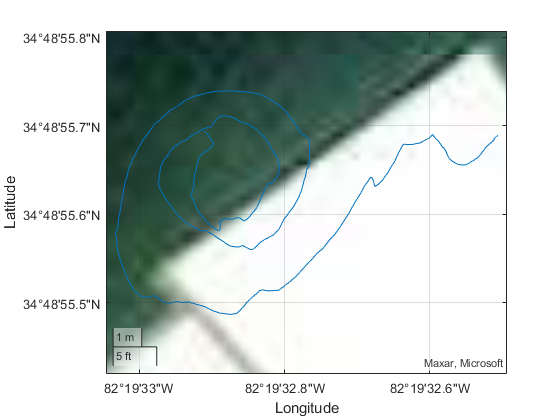

figure()
geoplot(gpsLat,gpsLon);
geobasemap satellite

## Wheel Encoder data processing

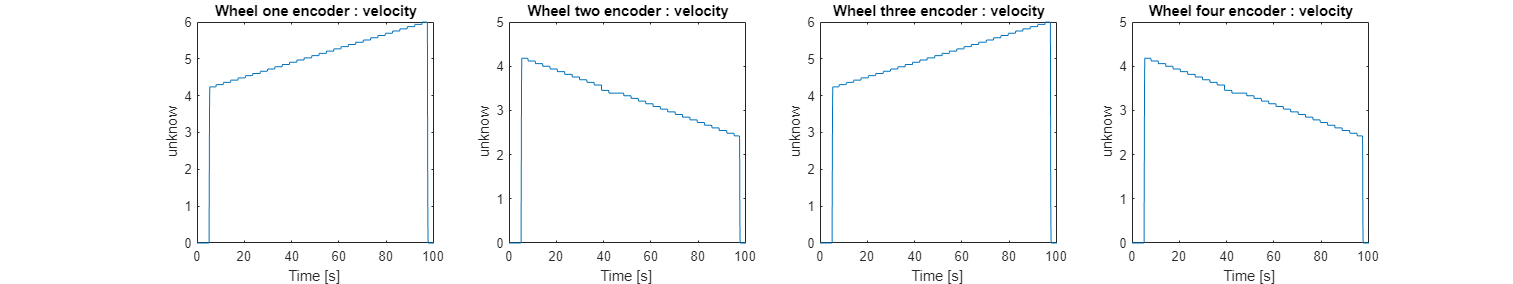

%flat_concrete.joint_states.Velocity
% Plotting each topic / any quantity becomes easier
we = clothoid_1.joint_states.Velocity;

% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = clothoid_1.joint_states.RelTime;

%Wheel 1:

for i=1:length(we)
    w1(i) = we{i,1}(1,1);
    w2(i) = we{i,1}(2,1);
    w3(i) = we{i,1}(3,1);
    w4(i) = we{i,1}(4,1);
end




f2 = figure();

subplot(1,4,1)
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,2)
plot(Reltime,w2)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,3)
plot(Reltime,w3)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,4)
plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

set(f2,'Units','normalized','Position',[0 0 1.5 0.5])

Two wheels on the same side are expected to have similar wheel velocites. Overlaying all the values on top of each other will help us identify those wheels

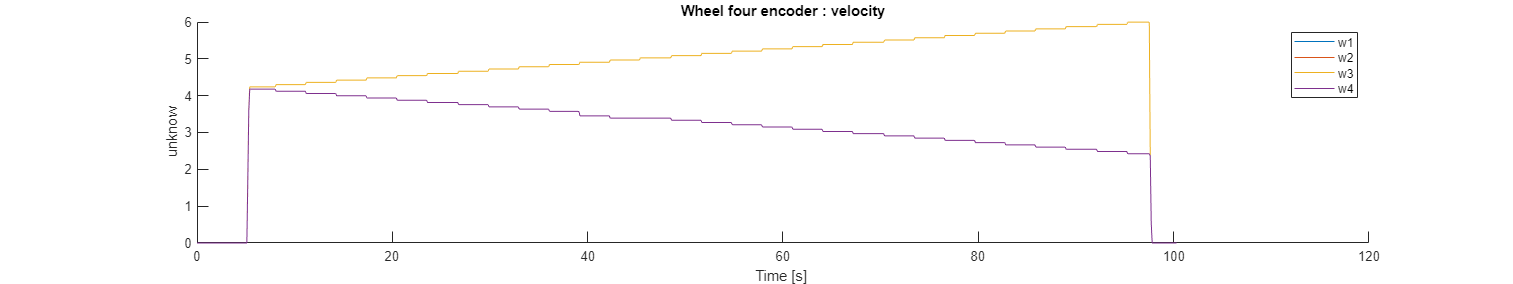

% How same or different are all the wheel velocities

%fignum = 1;
f3 = figure();

hold on
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w2)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w3)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
legend('w1','w2','w3','w4')
hold off

set(f3,'Units','normalized','Position',[0 0 1.5 0.5])

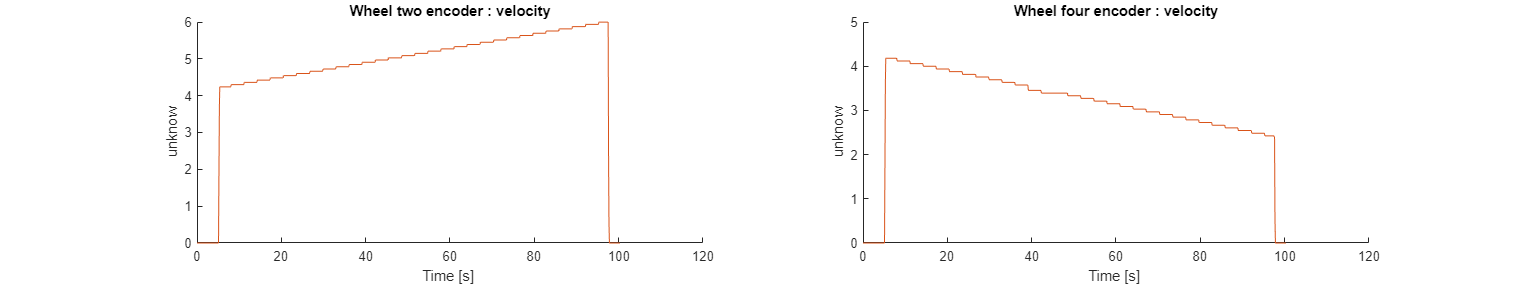

f4 = figure();

subplot(1,2,1)
hold on
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w3)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
hold off

subplot(1,2,2)
hold on
plot(Reltime,w2)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
hold off

set(f4,'Units','normalized','Position',[0 0 1.5 0.5])

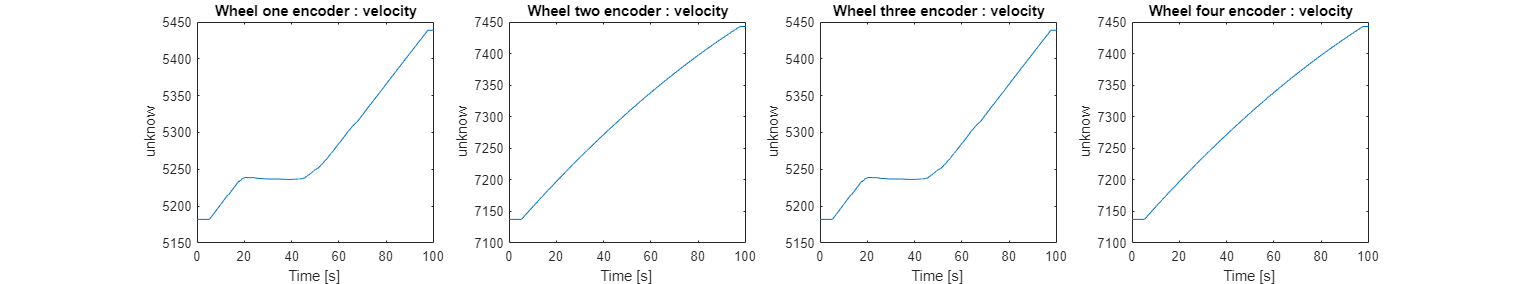

%Joint state position measurement

we_pos = clothoid_1.joint_states.Position;

% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = clothoid_1.joint_states.RelTime;

%Wheel 1:

for i=1:length(we_pos)
    w1p(i) = we_pos{i,1}(1,1);
    w2p(i) = we_pos{i,1}(2,1);
    w3p(i) = we_pos{i,1}(3,1);
    w4p(i) = we_pos{i,1}(4,1);
end



f5 = figure();

subplot(1,4,1)
plot(Reltime,w1p)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,2)
plot(Reltime,w2p)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,3)
plot(Reltime,w3p)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,4)
plot(Reltime,w4p)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
set(f5,'Units','normalized','Position',[0 0 1.5 0.5])

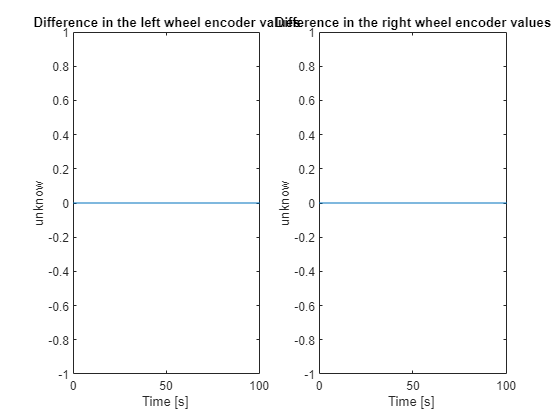

%Are pairs of the plots same or is there some measureable difference

f6= figure();
subplot(1,2,1)
plot(Reltime,w1p-w3p)
title('Difference in the left wheel encoder values')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,2,2)
plot(Reltime,w2p-w4p)
title('Difference in the right wheel encoder values')
xlabel('Time [s] ')
ylabel('unknow')